close all; clear; clc;

# KDE motor MC - heat testing

**file name**: MC_KDE_20181016.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** TEMP NOT RECORDED. 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('MC_KDE_20181016.mat');
time = MC_KDE_20181016(:,1);                       % [sec]
PWM = MC_KDE_20181016(:,2);                        % [micro sec]
Q = MC_KDE_20181016(:,4);                          % [ft.lbf]
T = MC_KDE_20181016(:,5);                          % [lbf]
Input_V = MC_KDE_20181016(:,6);                    % [Volts]
Input_A = MC_KDE_20181016(:,7);                    % [Amps]
rot_speed_rpm = MC_KDE_20181016(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = MC_KDE_20181016(:,9);                     % [Watts]
P_out_W = MC_KDE_20181016(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = MC_KDE_20181016(:,11);                 % [%]
Prop_Eff = MC_KDE_20181016(:,12);                  % [lbf/Watts]
Overall_Eff = MC_KDE_20181016(:,13);               % [lbf/Watts]  
ESC_Temp = MC_KDE_20181016(:,14);                  % [F]
Motor_Temp = MC_KDE_20181016(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

Settling_time = MC_KDE_20181016(:,17); % [s]

Max_Acc = MC_KDE_20181016(:,18);      % [RPM]

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

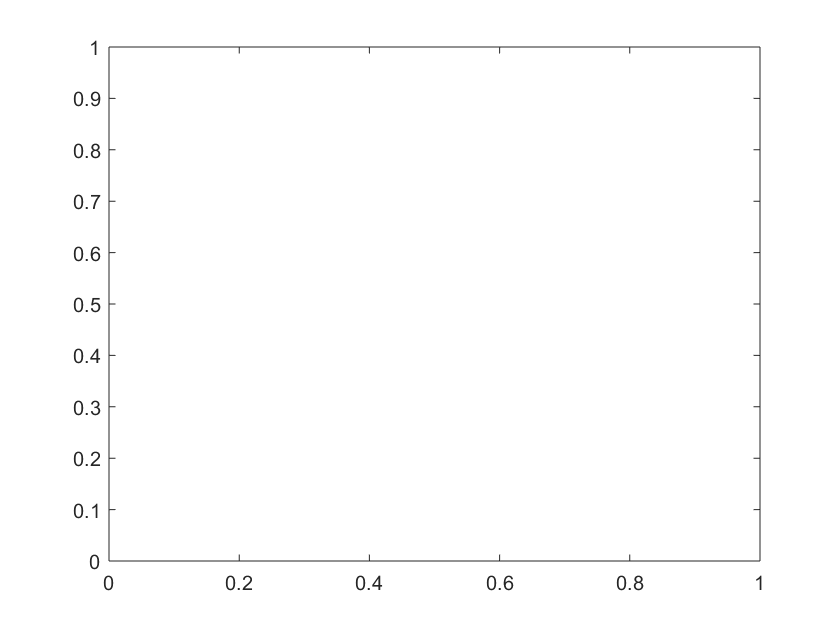

figure(1)
plot(PWM, Motor_Temp)

## Comparing Data to Momentum Theory

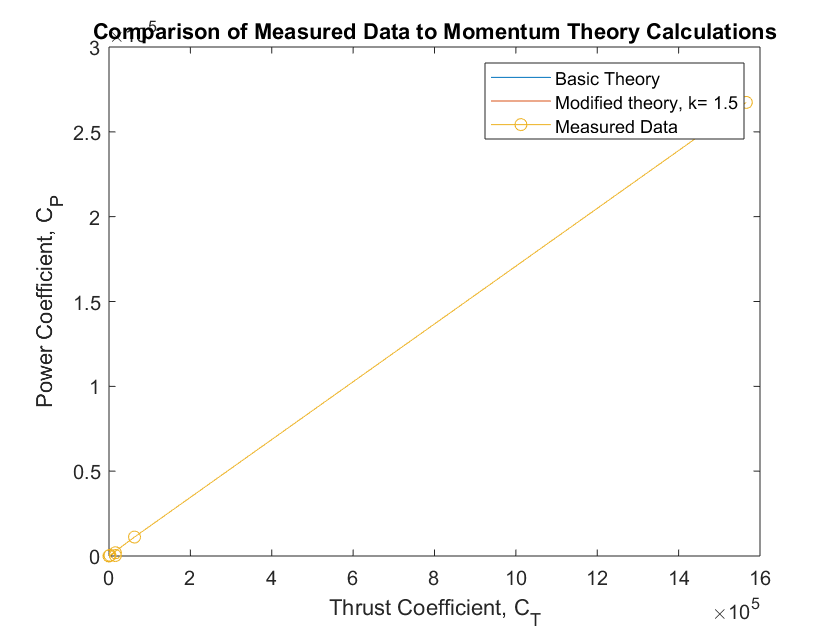

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T, C_P, 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data')